# Q1(b)

s = tf('s');
G = 50/(s*(s^2+10*s+50)*(s+5));
%G = prescale(ss(G));
Gd = 100/s;
[K1,CL,gamma,info] = loopsyn(G,Gd);

S = 1/(1+G*K1);
isstable(S)

ans = logical
   1


M = K1*S*G;
gam = norm(M,'inf')

gam = Inf

alpha = 1/gam

alpha = 0

# Q1(c)

OPT = balredOptions('StateElimMethod','Truncate');

K2 = (2*(s^2+10*s+50)*(s+5))/((s^2)*(1+ s/1e4));

order(K1)

ans = 11

order(K2)

ans = 3


K1 = balred(K1,2,OPT); % Loopsyn
K2 = balred(K2,2,OPT); % By-hand

isstable(K1)

ans = logical
   0


isstable(K2)

ans = logical
   1


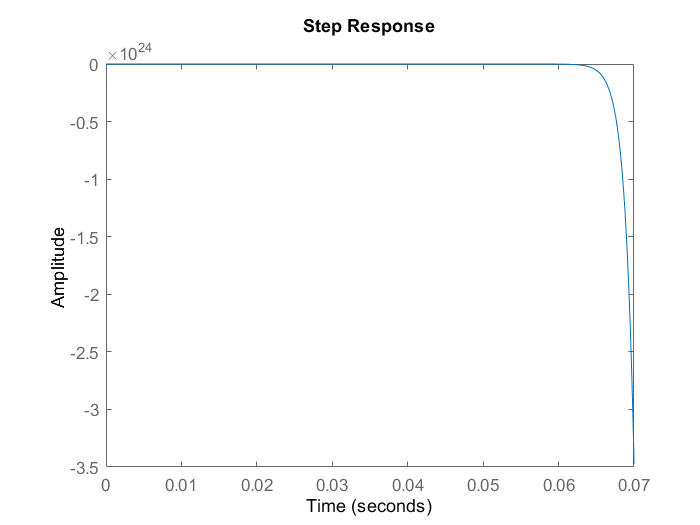


T1 = G*K1/(1 + G*K1);
T2 = G*K2/(1 + G*K2);
step(T1)

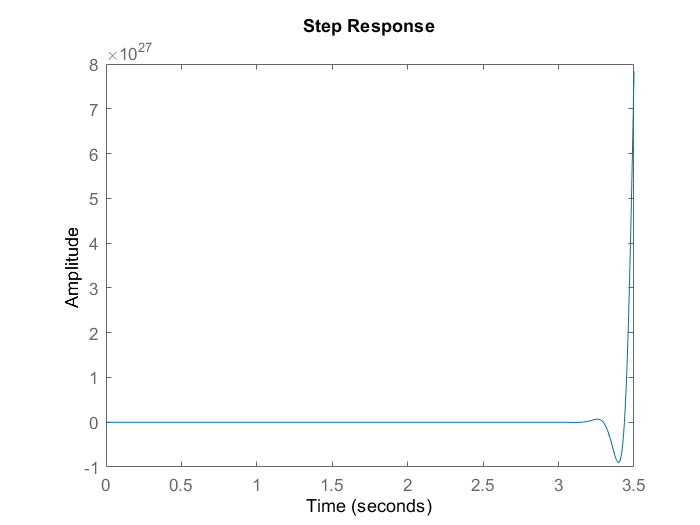

step(T2)


% Loopsyn controller
S = 1/(1+G*K1);
isstable(S)

ans = logical
   0


M = K1*S*G;
gam = norm(M,'inf')

gam = Inf

alpha = 1/gam

alpha = 0


% By-hand controller
S = 1/(1+G*K2);
isstable(S)

ans = logical
   0


M = K2*S*G;
gam = norm(M,'inf')

gam = 1.0025

alpha = 1/gam

alpha = 0.9975